# TP commande d’un système sur la base d’un modèle appris

## **Présentation du système et modélisation**

Le système est composé de 4 réservoirs d’eau, de deux pompes et deux vannes trois voies. Chaque réservoir contient un orifice par lequel le liquide s’écoule, du réservoir 3 vers le 1, du réservoir 4 vers le 2, puis des réservoirs 1 et 2 vers une cuve de rétention. Le but poursuivi est la recherche des lois de commandes capables d’asservir la hauteur d’eau dans les réservoirs 1 & 2 au travers des commandes des pompes 1 & 2.

## 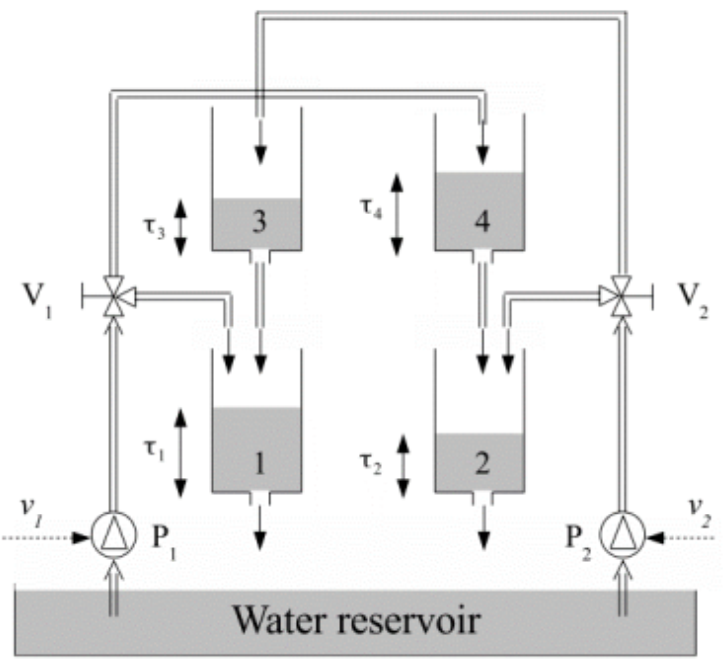 

## **Exploration des données d’apprentissage**

Le fichier data.mat contient les données nécessaires à l'entraînement  supervisé du réseau neuronal. Ces données sont préparées pour permettre au réseau de s'ajuster et de se perfectionner en la prédiction des variables d'état du système. Il est donc crucial de bien comprendre et d'utiliser correctement ces données pour obtenir un entraînement optimal du réseau. Le contenu du fichier est:

- inputs: Une matrice contenant une séquence de 12431 valeurs pour chacune des 2 entrées du système. Sa taille est donc de 2x12431.

- states: Une matrice contenant une séquence de 12432 valeurs de chacune des 4 variables d'état du système. Sa taille est donc de 4x12432. Notez qu'elle contient 1 donnée de plus que les entrées, car elle comprend l'état initial du système puis l'état du système pour chacune des 12431 entrées.

- umax, umin, xmax, xmin: Donnes neccesaires pour le normalization des donnes.

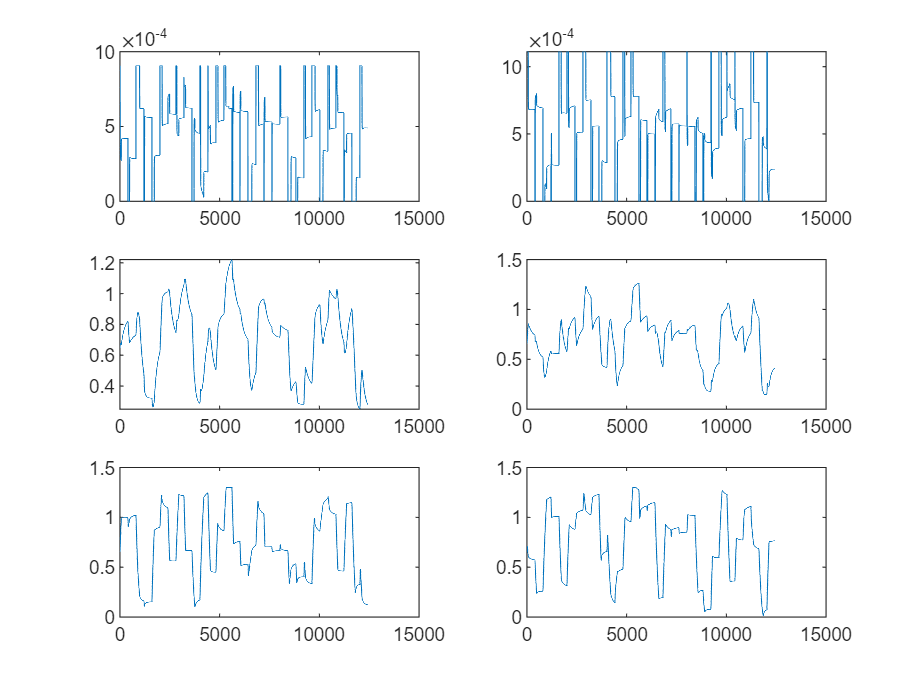

load data.mat;

x = [inputs;states(:,1:end-1)];
y = states(:,2:end);

for i = 1:6
    subplot(3,2,i);
    plot(x(i,:));
end

figure;

Pour prédire la valeur des variables d'état d'un système on a besoin d'un apprentissage de type régression. La régression est utilisée pour prédire une valeur numérique continue, contrairement à la  classification qui est utilisée pour prédire des catégories discrètes. Dans ce cas, la prédiction des valeurs de variables d'état est un processus continu et les valeurs prédites peuvent prendre n'importe quelle valeur réelle, il est donc nécessaire d'utiliser la régression pour entraîner le réseau à faire des prédictions précises.

La fonction de coût qui sera utilisée est l'erreur quadratique moyenne (MSE pour Mean Squared Error en anglais), qui mesure la différence moyenne entre les valeurs prédites et les valeurs réelles des données d'entraînement.

Nous effectuons la normalisation des données:

inputsNorm = (inputs-umin)./(umax-umin)

inputsNorm =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9998    0.8777    0.7396    0.6262    0.5407    0.4780    0.4325    0.3995    0.3758    0.3586    0.3461    0.3370    0.3305    0.3256    0.3221    0.3195    0.3175    0.3160    0.3148    0.3139    0.3132    0.3126    0.3121    0.3117    0.3113    0.3109    0.3106    0.3103    0.3100    0.3097    0.3094    0.3091    0.3089    0.3086    0.3083    0.3081    0.3078    0.3076    0.3073    0.3070    0.3068
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.

statesNorm = (states-xmin)./(xmax-xmin)

statesNorm =     0.4779    0.4779    0.4796    0.4813    0.4829    0.4846    0.4863    0.4880    0.4897    0.4914    0.4931    0.4948    0.4961    0.4970    0.4975    0.4977    0.4978    0.4977    0.4975    0.4972    0.4969    0.4966    0.4963    0.4959    0.4956    0.4953    0.4949    0.4946    0.4943    0.4940    0.4937    0.4935    0.4932    0.4930    0.4927    0.4925    0.4923    0.4922    0.4920    0.4918    0.4917    0.4915    0.4914    0.4913    0.4912    0.4911    0.4911    0.4910    0.4910    0.4909
    0.4779    0.4779    0.4806    0.4833    0.4860    0.4887    0.4914    0.4941    0.4968    0.4994    0.5021    0.5048    0.5074    0.5101    0.5127    0.5154    0.5180    0.5206    0.5231    0.5257    0.5282    0.5307    0.5332    0.5357    0.5381    0.5405    0.5429    0.5453    0.5476    0.5500    0.5523    0.5546    0.5568    0.5591    0.5613    0.5635    0.5657    0.5679    0.5700    0.5722    0.5743    0.5764    0.5785    0.5805    0.5825    0.5846    0.5866    0.5885    0.

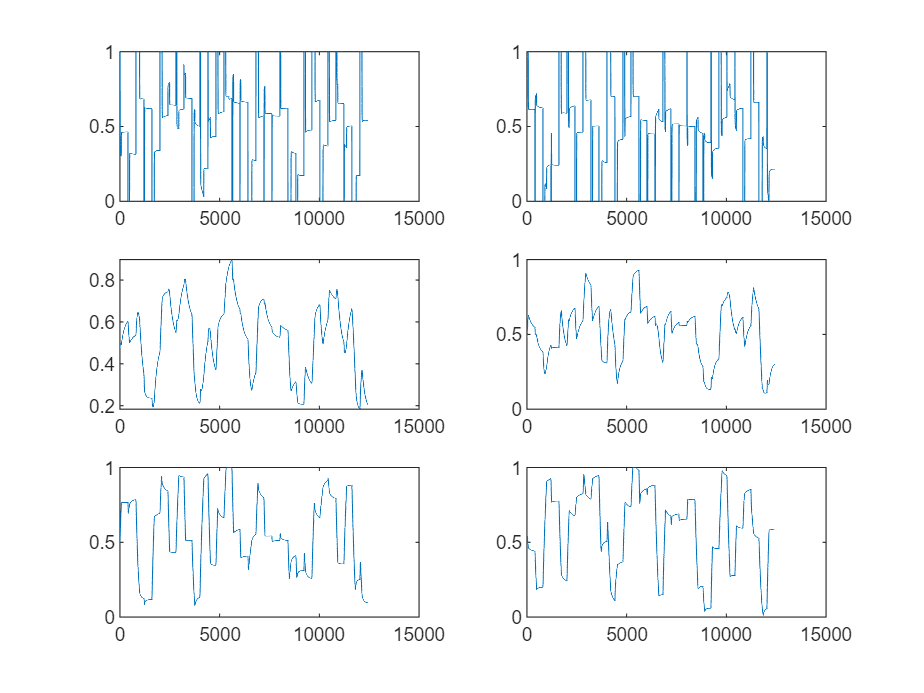

xNorm = [inputsNorm;statesNorm(:,1:end-1)];
yNorm = statesNorm(:,2:end);

for i = 1:6
    subplot(3,2,i);
    plot(xNorm(i,:));
end

figure;

Nous pouvons vérifier que toutes les valeurs sont comprises entre 0 et 1.

Ensuite, nous formons le jeu de données d'apprentissage. Pour ce faire, nous divisons les données en deux groupes. 80 % seront utilisés pour la formation du réseau et le reste pour la validation de la formation:

[xTrain, xTest,yTrain, yTest] = partitionData(xNorm,yNorm,0.2);

## **Apprentissage de la dynamique du système**

Nous passons ensuite à l'entraînement du réseau, pour lequel nous définissons d'abord les paramètres d'entraînement:

options = trainingOptions("sgdm", ...
    MaxEpochs=100, ...
    MiniBatchSize=100, ...
    Plots="training-progress", ValidationData={xTest',yTest'});

La structure du réseau neuronal donné consiste en quatre couches: une couche d'entrée, deux couches cachées et une couche de sortie. La première couche est la couche d'entrée, qui comporte six neurones correspondant aux deux entrées du système et aux quatre variables d'état. La deuxième couche est une couche entièrement connectée, qui contient un nombre variable de neurones cachés, déterminé par le paramètre "nH". Cette couche utilise une fonction d'activation sigmoïde pour introduire de la non-linéarité dans le réseau.

La troisième couche est également une couche entièrement connectée qui a quatre neurones, correspondant au nombre de sorties attendues du réseau. Enfin, la dernière couche est la couche de sortie, qui est une couche de régression avec une seule sortie. Cette couche a pour but de prédire la valeur de la variable de sortie en utilisant les valeurs des variables d'entrée.    

nTest = [1, 5, 10, 20];
infos = [];
nets = [];
train = false;
if train
    for nH = nTest
        %ntheta = (6+1)*nH + (nH+1)*4;
        layers = [featureInputLayer(6) fullyConnectedLayer(nH) sigmoidLayer fullyConnectedLayer(4) regressionLayer('Name','routput')];
        [net,info] = trainNetwork(xTrain',yTrain',layers,options);
        nets = [nets net];
        infos = [infos info.FinalValidationLoss];
    end
end

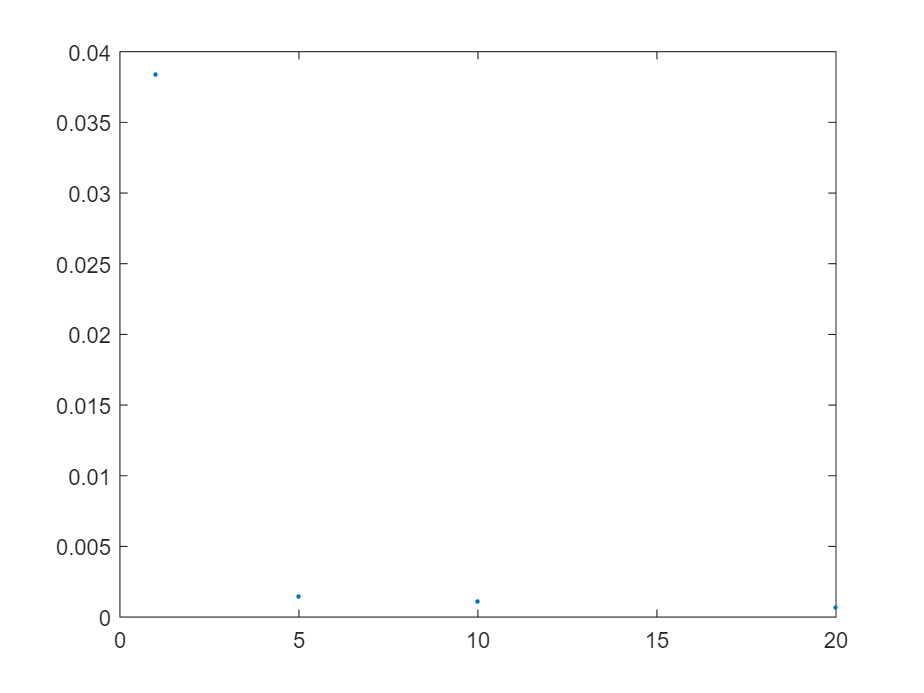

load infos.mat;
load nets.mat;
figure;
plot(nTest,infos,'.');

Avec 20 neurones, le réseau présente l'erreur finale la plus faible. Je vais m'en tenir à 20 neurones.

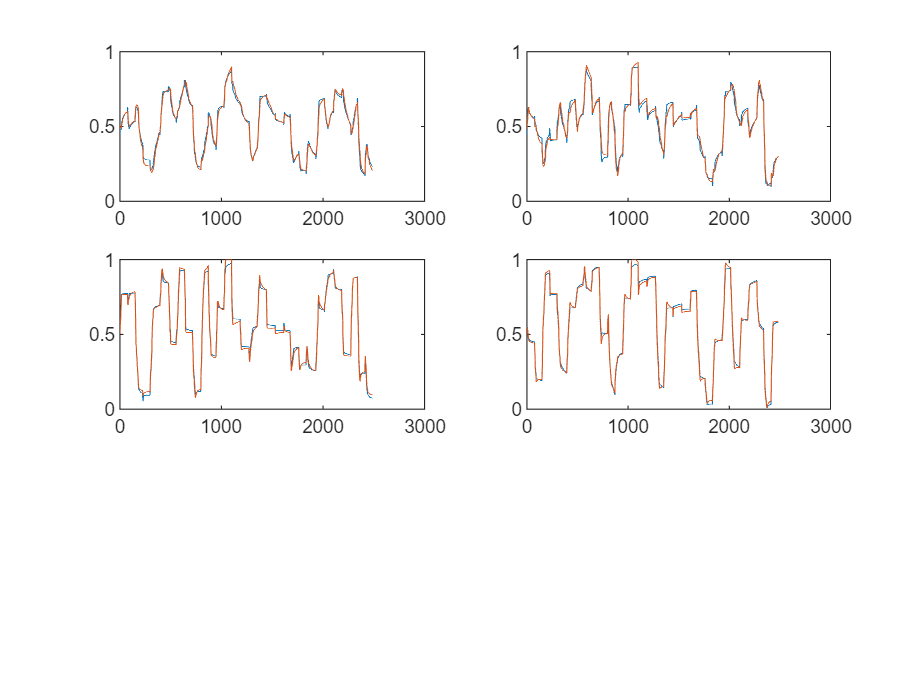

netOpt = nets(4);
yPre = predict(netOpt,xTest')';
figure;
for i = 1:4
    subplot(3,2,i);
    plot(yPre(i,:),'DisplayName','Predict');
    hold on;
    plot(yTest(i,:),'DisplayName','Test');
end

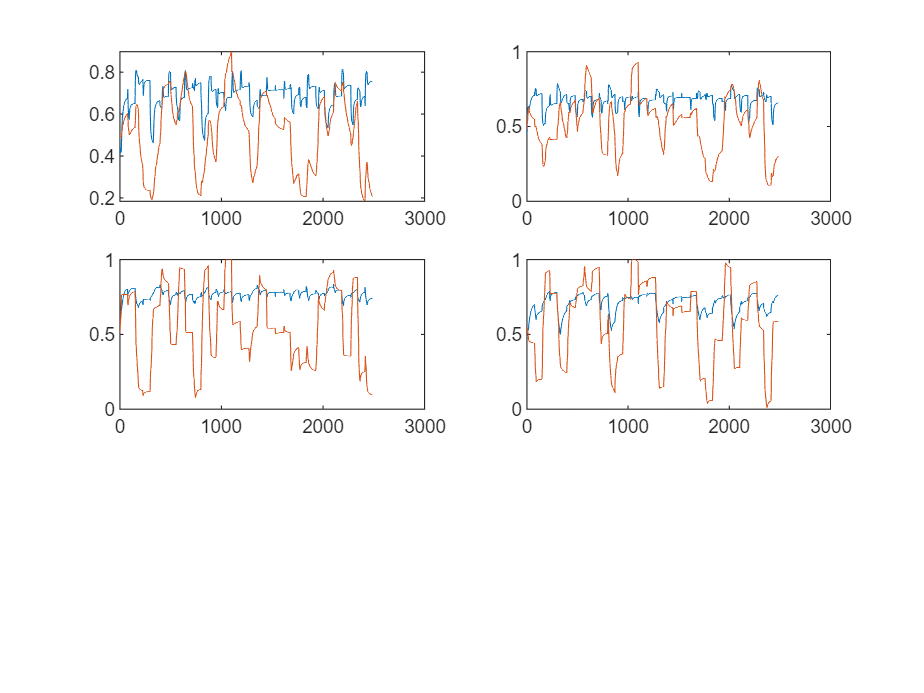

yPreR = [];
input = xTest(:,1)';
for i = 2:length(xTest)
    yPreR = [yPreR ; predict(netOpt,input)];
    input = [xTest(1:2,i)' yPreR(end,:)];
end
yPreR = [yPreR ; predict(netOpt,input)];

yPreR = yPreR';
figure;
for i = 1:4
    subplot(3,2,i);
    plot(yPreR(i,:),'DisplayName','Predict');
    hold on;
    plot(yTest(i,:),'DisplayName','Test');
end

## LQ

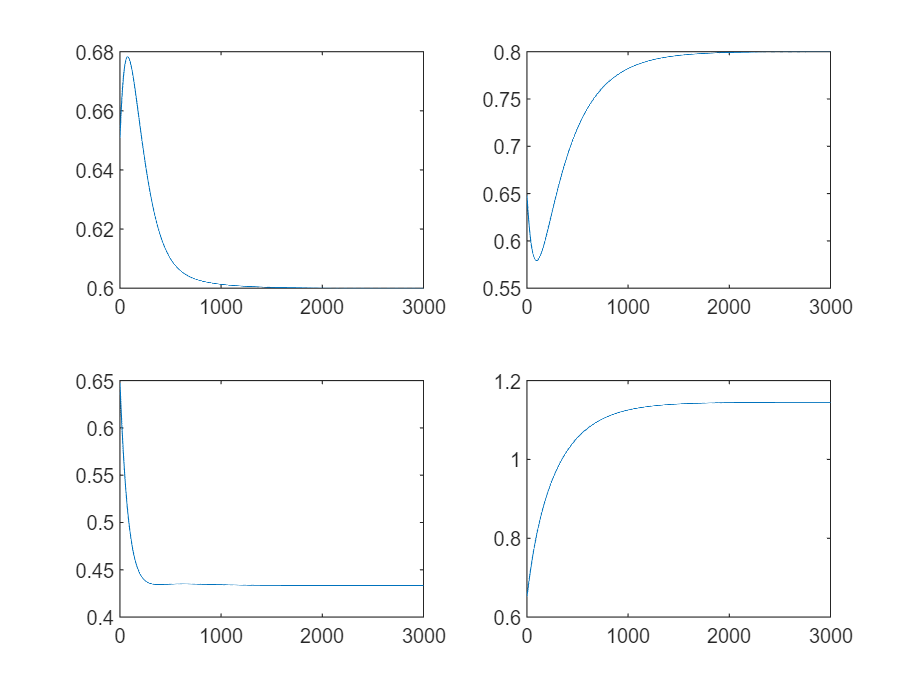

h = 0.01;
xRef = [0.6; 0.8; 0.4334; 1.1449];
uRef = 1e-4*[5.972; 4.505];
uRefN = (uRef-umin)./(umax-umin);
xRefN = (xRef-xmin)./(xmax-xmin);
pRef = [uRef; xRef];
pRefN = [uRefN; xRefN];
A = [dp(netOpt,pRefN',3,h) dp(netOpt,pRefN',4,h) dp(netOpt,pRefN',5,h) dp(netOpt,pRefN',6,h)];
B = [dp(netOpt,pRefN',1,h) dp(netOpt,pRefN',2,h)];

Q = 1*[1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
R = 1000*[1 0;
          0 1];
[Kn,S,e] = dlqr(A,B,Q,R);
K = (Kn'.*xmax)'.*umax;
x2 = [];
L =[];
x1 = states(:,1);
for i = 1:3000
    x2 = phi_qtp(x1,uRef-K*(x1-xRef));
    x1 = x2';
    L = [L x1];
end

for i = 1:4
    subplot(2,2,i);
    plot(L(i,:));
end

function dR = dp(net,point,varIndex,h)
    dir = zeros(1,6);
    dir(varIndex) = 1;
    dR = ((predict(net,point+h*dir)-predict(net,point))/h)';
end

function [xTrain, xTest, yTrain, yTest] = partitionData(x,y,pTest)
    n = length(x);
    hpartition = cvpartition(n,'Holdout',pTest);
    idTest = test(hpartition);
    idTrain = training(hpartition);
    xTrain = x(:,idTrain);
    xTest = x(:,idTest);
    yTrain = y(:,idTrain);
    yTest = y(:,idTest);
end